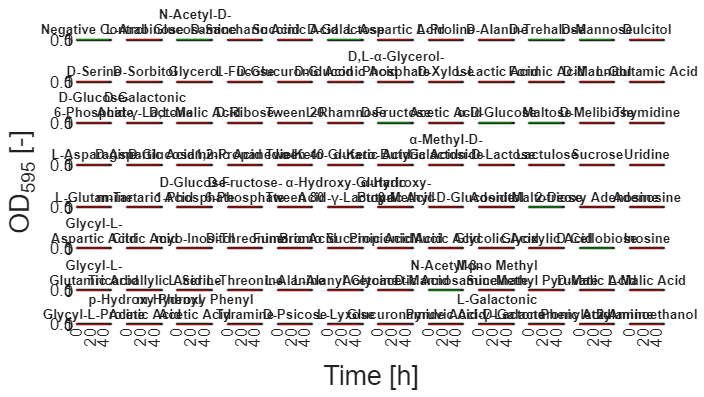

function out = split_title_halfword(s, maxLen)
    % Split title near the half, using "-" or space.
    % If split at "-", keep the "-" with the first line.
    % If split at " ", just split and remove the space.

    s = char(s);
    n = strlength(s);

    if n <= maxLen
        out = s;
        return;
    end

    % Ideal midpoint
    mid = ceil(n / 2);

    % Find all possible split positions
    splitPositions = regexp(s, '[ -]');   % matches " " OR "-"

    if isempty(splitPositions)
        out = s;   % no valid split character found
        return;
    end

    % Choose the split position closest to midpoint
    [~, idx] = min(abs(splitPositions - mid));
    splitPos = splitPositions(idx);

    % Determine the exact split behavior
    if s(splitPos) == '-'                 % hyphen case → keep it
        firstLine  = s(1:splitPos);       % keep '-'
        secondLine = s(splitPos+1:end);
    else                                  % space case → drop the space
        firstLine  = s(1:splitPos-1);
        secondLine = s(splitPos+1:end);
    end

    % Clean whitespace
    firstLine  = strtrim(firstLine);
    secondLine = strtrim(secondLine);

    out = sprintf("%s\n%s", firstLine, secondLine);
end

%% LOAD PM1 DATA
T = readtable("D:\growth_experiments_results\results_lactococcus\PM1_Biolog\data_Excel\PM1 - NZ9000(2) - ZMB1-glucose_an.xlsx", "ReadVariableNames", false);

time_sec = T{:,2};                % column B = time [s]
time_hr  = time_sec / 3600;       % convert to hours

data = T{:,3:98};                 % columns C to CV (96 wells)

%% GLOBAL MAX OD FOR Y-LIMIT
global_max_od = max(data(:));
y_upper = global_max_od * 1.1;

%% WELL IDS IN 96-WELL ORDER
rows = 'ABCDEFGH';
cols = 1:12;

well_ids = cell(1,96);
k = 1;
for r = 1:8
    for c = 1:12
        well_ids{k} = sprintf('%c%02d', rows(r), cols(c));
        k = k + 1;
    end
end

%% WELL NAME MAP (PM1 annotations)
wells = struct( ...
    'A01','Negative Control', ...
    'A02','L-Arabinose', ...
    'A03','N-Acetyl-D-Glucosamine', ...
    'A04','D-Saccharic Acid', ...
    'A05','Succinic Acid', ...
    'A06','D-Galactose', ...
    'A07','L-Aspartic Acid', ...
    'A08','L-Proline', ...
    'A09','D-Alanine', ...
    'A10','D-Trehalose', ...
    'A11','D-Mannose', ...
    'A12','Dulcitol', ...
    'B01','D-Serine', ...
    'B02','D-Sorbitol', ...
    'B03','Glycerol', ...
    'B04','L-Fucose', ...
    'B05','D-Glucuronic Acid', ...
    'B06','D-Gluconic Acid', ...
    'B07','D,L-α-Glycerol-Phosphate', ...
    'B08','D-Xylose', ...
    'B09','L-Lactic Acid', ...
    'B10','Formic Acid', ...
    'B11','D-Mannitol', ...
    'B12','L-Glutamic Acid', ...
    'C01','D-Glucose-6-Phosphate', ...
    'C02','D-Galactonic Acid-γ-Lactone', ...
    'C03','D,L-Malic Acid', ...
    'C04','D-Ribose', ...
    'C05','Tween 20', ...
    'C06','L-Rhamnose', ...
    'C07','D-Fructose', ...
    'C08','Acetic Acid', ...
    'C09','α-D-Glucose', ...
    'C10','Maltose', ...
    'C11','D-Melibiose', ...
    'C12','Thymidine', ...
    'D01','L-Asparagine', ...
    'D02','D-Aspartic Acid', ...
    'D03','D-Glucosaminic Acid', ...
    'D04','1,2-Propanediol', ...
    'D05','Tween 40', ...
    'D06','α-Keto-Glutaric Acid', ...
    'D07','α-Keto-Butyric Acid', ...
    'D08','α-Methyl-D-Galactoside', ...
    'D09','α-D-Lactose', ...
    'D10','Lactulose', ...
    'D11','Sucrose', ...
    'D12','Uridine', ...
    'E01','L-Glutamine', ...
    'E02','m-Tartaric Acid', ...
    'E03','D-Glucose-1-Phosphate', ...
    'E04','D-Fructose-6-Phosphate', ...
    'E05','Tween 80', ...
    'E06','α-Hydroxy-Glutaric Acid-γ-Lactone', ...
    'E07','α-Hydroxy-Butyric Acid', ...
    'E08','β-Methyl-D-Glucoside', ...
    'E09','Adonitol', ...
    'E10','Maltotriose', ...
    'E11','2-Deoxy Adenosine', ...
    'E12','Adenosine', ...
    'F01','Glycyl-L-Aspartic Acid', ...
    'F02','Citric Acid', ...
    'F03','myo-Inositol', ...
    'F04','D-Threonine', ...
    'F05','Fumaric Acid', ...
    'F06','Bromo Succinic Acid', ...
    'F07','Propionic Acid', ...
    'F08','Mucic Acid', ...
    'F09','Glycolic Acid', ...
    'F10','Glyoxylic Acid', ...
    'F11','D-Cellobiose', ...
    'F12','Inosine', ...
    'G01','Glycyl-L-Glutamic Acid', ...
    'G02','Tricarballylic Acid', ...
    'G03','L-Serine', ...
    'G04','L-Threonine', ...
    'G05','L-Alanine', ...
    'G06','L-Alanyl-Glycine', ...
    'G07','Acetoacetic Acid', ...
    'G08','N-Acetyl-β-D-Mannosamine', ...
    'G09','Mono Methyl Succinate', ...
    'G10','Methyl Pyruvate', ...
    'G11','D-Malic Acid', ...
    'G12','L-Malic Acid', ...
    'H01','Glycyl-L-Proline', ...
    'H02','p-Hydroxy Phenyl Acetic Acid', ...
    'H03','m-Hydroxy Phenyl Acetic Acid', ...
    'H04','Tyramine', ...
    'H05','D-Psicose', ...
    'H06','L-Lyxose', ...
    'H07','Glucuronamide', ...
    'H08','Pyruvic Acid', ...
    'H09','L-Galactonic Acid-γ-Lactone', ...
    'H10','D-Galacturonic Acid', ...
    'H11','Phenylethylamine', ...
    'H12','2-Aminoethanol' ...
);


%% PARAMETERS
numRows = 8;
numCols = 12;

ref_curve = data(:,1);     % reference = A01
ref_max = max(ref_curve);

t_first = min(time_hr);
t_last  = max(time_hr);

x_min = max(0, floor(t_first - 4));
x_max = ceil(t_last + 4);

forced_ticks = [20 40 60];

%% PLOT 96-WELL PLATE
figure('Units','normalized','Position',[0 0 1 1]);
t = tiledlayout(numRows, numCols);
t.Padding = 'compact';
t.TileSpacing = 'compact';

for i = 1:96
    ax = nexttile;
    ax.LineWidth = 1.4;
    curve = data(:,i);

    % Color by fold-change vs. A01
    curr_max = max(curve);
    fold_change = curr_max / ref_max;
    plotColor = [0 0.6 0] * (fold_change >= 2) + ...
                [0.8 0 0] * (fold_change <  2);

    plot(time_hr, curve, 'Color', plotColor, 'LineWidth', 1.4);
    ylim([0 y_upper]);
    fixed_yticks = 0 : 0.5 : y_upper;   % adjust spacing as you prefer
    xlim([x_min x_max]);

    % Titles: show every well (recommended for PM1)
    rawTitle  = wells.(well_ids{i});
    niceTitle = split_title_halfword(rawTitle, 20);   % 20‑character threshold
    title(niceTitle, 'FontSize', 8);

    % Axis formatting
    row = ceil(i / numCols);
    col = i - (row-1)*numCols;

    % X ticks
    xt = unique([ax.XTick forced_ticks]);
    xt(xt == 50) = [];
    xt = xt(xt >= x_min & xt <= x_max);
    ax.XTick = xt;

    % Y ticks
    yt = unique([ax.YTick 0.5]);
    ax.YTick = fixed_yticks;

    fs = 10;   % smaller because 96 wells

    % Y-axis labels
    if col ~= 1
        ax.YTickLabel = [];
    else
        ax.YAxis.FontSize = fs;
    end

    % X-axis labels
    if row ~= numRows
        ax.XTickLabel = [];
    else
        ax.XAxis.FontSize = fs;
    end
end

xlabel(t, "Time [h]", "FontSize", 16);
ylabel(t, "OD_{595} [-]", "FontSize", 16);